*************************************************************


working on file:Step_1


  Name         Size                     Bytes  Class     Attributes

  hdfData      8x2587038            165570432  double              



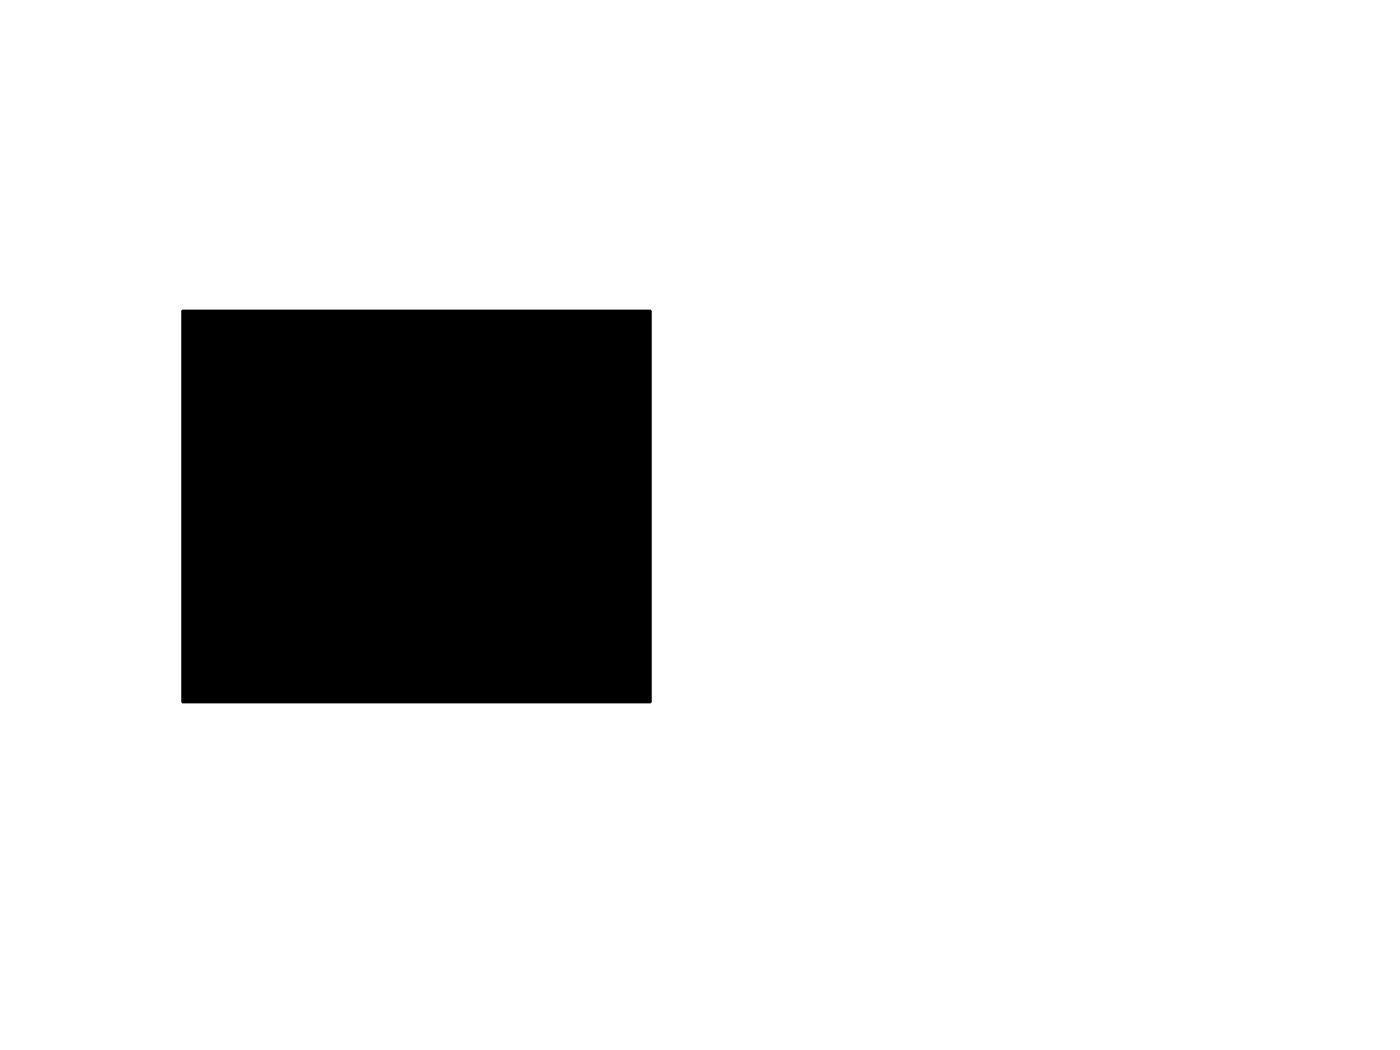


close all
clear all
clc
cd('D:\DIC\Matlab')

% profile on
deadZone = 0.3;  %dead area around discontinuities for registration (mm)
fDoRegistration = true; %register the data (otherwise read from parm file)
fSubDispFromProfile = true;%false; %subtract the displacement data from the profile to keep profiles at 0,0
fRemoveOutliers = true; %remove data with displacements greater than numStdDev from the mean
numStdDev = 3;
fSaveRegData = true;%true %save the registered data

fSaveRegGrid_w = true; %W: I added these to avoid saving files 

fSaveRegGrid = true;%true  %create and save a regular grid of registered data
fSaveTPlotGrid = false;  %save a regular grid of data for techplot
fCalcProfileNoise = false;%true; %calculate the noise in the profile from the 5 samples
fSaveGlobalStats = true; %save the global stats to the excel sheet
fExitOnEnd = false; %exit the program at the end

%setup the grid parameters
[gridParms,minCounts] = GetGridParms;

%setup the output matricies for the EXCEL sheet
outputIdx = 0;
outputNumData = [];
outputTextData = strings([1,4]);

%select the groups to work on
% groups = [310 311 312 313 314];  %group 3 system 1
% groups = [220 221 222 223 224];  %group 2 system 2
% groups = [210 211 212 213 214];  %group 2 system 1
%groups = [310];

% sysgroups = [310; %group 3 system 2 GREWER
%                320];  
% sysgroups = [220;...%group 2 system 2 LAVA
%             210];  %group 2 system 1
% sysgroups = [410;...
%                420]; %group 3 system1 and 2 Dantec
% groups = [];
 sysgroups = [510;...
               520]; % LaVision
% sysgroups = [115;125]; % Sandia 

% sysgroups = [210 211 212 213 214];  %group 3 system 1 GREWER

for grp = 1:size(sysgroups,1)
    groups = sysgroups(grp,:);
    
    if grp == 1
       fildir = 'D:\DIC\Translate\35-mm\Step01 00,00-sys1-0000_0.tif';
    elseif grp == 2
       fildir = 'D:\DIC\Translate\16-mm\Step01 00,00-sys2-0000_0.tif';
    end
    im = imread(fildir);
    im = repmat(im,1,1,3);
    
for iGroupNum = 1:size(groups,2)
  groupNum = groups(iGroupNum);
  
  %Get the filenames for the test
  [fileNames, testDir, sysNum, baseDir, appliedStep, dataSet, groupID, stepVals]=DicDataFileNames_v2(groupNum);  

  %setup the filenames for the analysis
  testName = strrep(testDir,'\','_');
  testDir = strcat(testDir, '\');
  
  %get the parameters that describe the surface
  [theoBoundries,theoCorners,fitBoundries,areaCoef] = FillFitParms(sysNum, deadZone);
  
  %Make regular grid data from all the files
  for iFile = 1%2:size(fileNames,1)
    %setup the input file name
    disp('*************************************************************');
    disp(strcat('working on file: ',fileNames(iFile)));
    fileBase = strcat(fileNames(iFile));
    DICFileBase = strcat(baseDir, testDir, fileBase);
    DICInputFile = strcat(DICFileBase, '.mat');
    zoneName = strcat(fileBase, ' ');  %%move to techplot area
    
    %Read the data and then seperate into the sepaerate areas
    whos('-file', DICInputFile);
    fLoad = load(DICInputFile);
    
    %Adding lines to analyze the codes which have columns data instead of
    %rows: Specifically for LaVision
    if isfield(fLoad,'hdfData')
        fLoad.hdfData = fLoad.hdfData';
    end
    
    A_1 = fLoad.(cell2mat(fieldnames(fLoad)));
    dicmat = A_1;
    ind = sub2ind([size(im,1) size(im,2)],dicmat(:,2),dicmat(:,1));

    Zp = NaN([size(im,1) size(im,2)]);
    Zp(ind) = dicmat(:,5);
    
    figure(1)
    subplot(1,2,1)
    imshow(im)
    hold on 
    p = pcolor(Zp);
    p.LineStyle = 'none';p.EdgeColor = 'flat';p.FaceColor = 'flat';

    %strip out any nan entries
    disp(strcat('-rows before StripNan', num2str(size(A_1,1))));
    initRows = size(A_1, 1);
    NaNRows = size(A_1,1);
    A_1 = rmmissing(A_1);
    NaNRows = NaNRows - size(A_1,1);    
    disp(strcat('-rows after StripNan', num2str(size(A_1,1))));
        
    %fill the world and image data arrays
    imgData = A_1(:,1:2);
    profData = A_1(:,3:5);
    dispData = A_1(:,6:8);
    
    Zpp = NaN([size(im,1) size(im,2)]);
    Zpp(ind) = A_1(:,5);
    
    subplot(1,2,2)
    imshow(im)
    hold on 
    p = pcolor(Zpp);
    %p.EdgeColor = 'none';
    p.LineStyle = 'none';p.EdgeColor = 'flat';p.FaceColor = 'flat';
   
  end
end

end

toc
if fExitOnEnd
  exit;
end




% dicmat = A_1;
% fildir = 'D:\DIC\Translate\35-mm\Step01 00,00-sys1-0000_0.tif';
% im = imread(fildir);
% [max(dicmat(:,1)),max(dicmat(:,2))]
% ind = sub2ind(size(im),dicmat(:,2),dicmat(:,1));
% 
% Z = NaN(size(im));
% Z(ind) = dicmat(:,5);
% figure(1)
% imshow(im)
% hold on 
% p = pcolor(Z);
% p.EdgeColor = 'none';
